# **RT-QIBC analysis**

**FarRed1: chromatin-bound MCM2 stain**

**POI(:,3): CRL4Cdt2 activation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {

         'DMSO MCM',2,2:6,1:9,[0 0 0]; %1
         'DMSO HA',3,2:6,1:9,[0 0 0]; %1
         
         'Dox MCM',2,7:11,1:9,[0 0 0]; %1
         'Dox HA',3,7:11,1:9,[0 0 0]; %1
    };


load([dataDir filesep 'C210_data.mat'],'S');
%S = loadData(conditions, dataDir);
framesPerHr = 60/4;
frameDrugAdded = 0;                                                  
frameEdU = 0;
folding = 0;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames; 
xTime = (xFrames-1)./framesPerHr;

map = nikon_well_offset_new(conditions,9,1);
POI_time = arrayfun(@(x) (numFrames - x.POI + repmat(cell2mat(map.values(x.shot)),1,size(x.POI,2)))/framesPerHr, S,'UniformOutput',false);
[S.POI_time] = POI_time{:};

**Set thresholds**

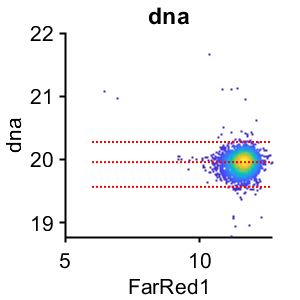

%% set G1 phase gates
cond=1;
gates = {'dna'};
plotting = {'FarRed1'};
prctiles = {[1 50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) > 2 & S(cond).POI_time(:,1) < 3  ;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

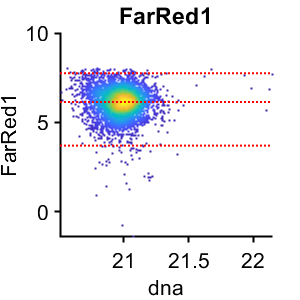


%% set G2 phase gates
cond=1;
gates = {'FarRed1'};
plotting = {'dna'};
prctiles = {[1 50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,5) > 0 & S(cond).YFP1 < 2^4 & S(cond).dna > 2^20.5 & S(cond).FarRed1 < 2^8;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G2']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G2'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
    if strcmp(gates{i},'FarRed1')
        g2cellsmcm = ydata;
    end

end

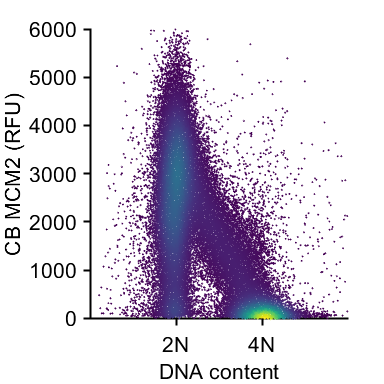

ans = 96343

conds=[1];

xval = 'allDNA';
yval = 'allFarRed1';

for i = 1:length(conds)
    condition = conds(i);
    xdata = (S(condition).(xval)/gate.dna_G1(2));
    ydata =  ((S(condition).(yval)));
    inds =  ydata < 6000 & xdata > 0 & xdata < 3;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    colormap('viridis')
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim([0 3])
    xticks([1 2])
    xticklabels({'2N','4N'})
%     ylim([3 13]);
%     ylim([2 13])
    ylabel('CB MCM2 (RFU)');
    xlabel('DNA content');
%     title(conditions{condition,1});
%     axis square
    print_pdf([pwd() '\Figs\dnavsMCM.pdf'])
    length(xdata)
end

**Time since CRL MCM levels for export**

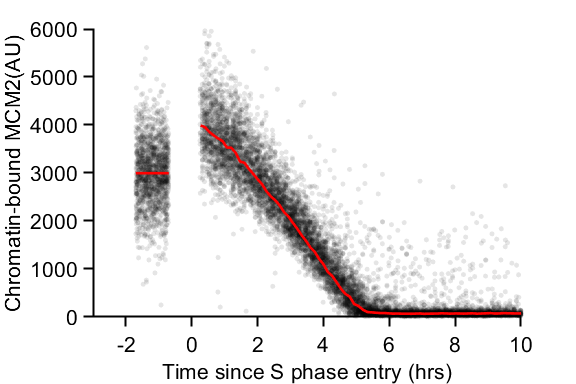

cond=1;
poiAligned=3;
offset=0;


rng(1)
gateVals = {{'YFP1'},{'YFP1'},{},{}};
rangeVals = {{[0 2^4.5]},{[0 2^4.5]},{},{}};
edges = (4/framesPerHr:(2/framesPerHr):17);


ind= ~isnan(S(cond).POI_time(:,poiAligned(1))) & ...
    gate_vals(S(cond), gateVals{1}, rangeVals{1});

xdata = S(cond).POI_time(ind,poiAligned);
ydata = [];
ydata(:, 1) = (S(cond).FarRed1(ind)) ;

[binData, edges] = bin_xy(xdata, ydata, {'mean','median'},...
    'Edges',edges);
midpoints = edges;
midpoints = midpoints(1:end-1);

cond = 1;
inds = S(cond).POI_time(:,1) >= .5 & S(cond).POI_time(:,1) <= 2 & S(cond).YFP1 < 2^4.5;
g1cellsmcm = S(cond).FarRed1(inds);


f1 = figure('Units', 'Inches', 'Position', [0, 0, 6, 4]);
hold on
subG1 = randsample((g1cellsmcm),1500);
subs_cells = randsample(size(ydata,1),10000);
subs = false(size(ydata,1),1);
subs(subs_cells) = true;
% subs = subs & ydata(:,1) < 2 & ydata(:,1) > -.1;
fakexg1 = rand(size(subG1)) - 1.7;
%dscatter(xdata,ydata2);
scatter(xdata(subs),ydata(subs,1),15,'k','filled','MarkerFaceAlpha',.1)
scatter(fakexg1,subG1 ,15,'k','filled','MarkerFaceAlpha',.1)
plot(midpoints,binData(1).median,'r','LineWidth',2);
plot([-1.7 -.7],[mean(g1cellsmcm) mean(g1cellsmcm)],'r','LineWidth',2)
ylim([0 6000]);
xlim([-3 10]);
ylabel('Chromatin-bound MCM2(AU)');xlabel({'Time since S phase entry (hrs)'});
%title(conditions{conds(i),1});
% h=hline(log2(gate.FarRed1_G1(2)),'k');
hold off
print_pdf([pwd() '\Figs\MCM_timesinceS.pdf'])